# Calculo del Flux másico de transferencia de masa - Ethaline

Tabla de datos de Amphlett & Choi (2021)

Estos datos son temperatura ambiente aproximadamente 20°C (293.15 K).

water_content_Eth=[0;0;5;5;5;10;10;10;15;15;15;20;20;30;30];
coef_extincion_Eth=[0.01626;0.00990;0.01395;0.00516;0.00545;0.01229;0.00470;0.00489;0.01016;0.00358;0.00374;0.00868;0.00283;0.00828;0.00330];

Temperature=293.15*ones(length(water_content_Eth),1);
concentr_Eth=1./coef_extincion_Eth;
table(Temperature,water_content_Eth,coef_extincion_Eth,concentr_Eth)

ans = 15×4 table
    Temperature    water_content_Eth    coef_extincion_Eth    concentr_Eth
    ___________    _________________    __________________    ____________

      293.15               0                 0.01626             61.501   
      293.15               0                  0.0099             101.01   
      293.15               5                 0.01395             71.685   
      293.15               5                 0.00516              193.8   
      293.15               5                 0.00545             183.49   
      293.15              10                 0.01229             81.367   
      293.15              10                  0.0047             212.77   
      293.15              10                 0.00489              204.5   
      293.15              15                 0.01016             98.425   
      293.15         

Cálculo de la densidad

Densidad_Eth= 1.2939+(-0.0012)*water_content_Eth+(-0.0006)*Temperature

Densidad_Eth =     1.1180
    1.1180
    1.1120
    1.1120
    1.1120
    1.1060
    1.1060
    1.1060
    1.1000
    1.1000


Cálculo de la viscosidad

Viscosidad_Eth=zeros(length(water_content_Eth),1);
% Importación de los datos sin outliers para ajuste del modelo
import_train_data=load("Data_Visc_Rel_NoOutliers.mat");
aux1=import_train_data.data1(:,1);
aux2=import_train_data.data1(:,2);
aux3=import_train_data.data1(:,3);
data_train_visc=[aux1 aux2 aux3];
data_train_visc=array2table(data_train_visc,"VariableNames", ...
    {'Mass_percent_Water','Temperature(K)','Viscosity(cP)'});
% Llamado a la función del modelo seleccionado
[regre_visc_rel, ~] = MediumGaussianSVM_Visc_Ethaline(data_train_visc);

% Creacion del vector para predicción
aux_calc_viscosidad=[water_content_Eth Temperature Viscosidad_Eth];
aux_calc_viscosidad=array2table(aux_calc_viscosidad,"VariableNames", ...
    {'Mass_percent_Water','Temperature(K)','Viscosity(cP)'});
% Cálculo de la viscosidad
Viscosidad_Eth=regre_visc_rel.predictFcn(aux_calc_viscosidad)

Viscosidad_Eth =   230.6227
  230.6227
  171.4969
  171.4969
  171.4969
  115.8835
  115.8835
  115.8835
   68.8653
   68.8653


Peso Molecular Promedio

% Datos de pesos moleculares como 2 componentes (Suma-->xiMi)
PM_Reline=87.92;
PM_Ethaline=91.22;
PM_Maline=136.85;
PM_water=18.02;
% Conversión de base de cálculo másica a molar
moles_Agua=water_content_Eth/PM_water;
moles_Ethaline=(100-water_content_Eth)/PM_Ethaline;
moles_totales=moles_Agua+moles_Ethaline;
fraccion_molar_agua=moles_Agua./moles_totales;
fraccion_molar_ethaline=moles_Ethaline./moles_totales;
% Cálculo del peso molecular de la mezcla
PM_Mezcla=fraccion_molar_agua*PM_water+fraccion_molar_ethaline*PM_Ethaline

PM_Mezcla =    91.2200
   91.2200
   75.8203
   75.8203
   75.8203
   64.8692
   64.8692
   64.8692
   56.6822
   56.6822


Volumen molar

Vol_molar=PM_Mezcla./Densidad_Eth

Vol_molar =    81.5914
   81.5914
   68.1831
   68.1831
   68.1831
   58.6515
   58.6515
   58.6515
   51.5288
   51.5288


Difusividad

fact_aso=1; % INPUT Factor de asociacion chi desde 1 hasta 2.6
% Cálculo del coeficiente de difusividad
Diff=(7.4e-8)*((fact_aso.^0.5*PM_Mezcla.^0.5.*Temperature)./(Viscosidad_Eth.*Vol_molar.^0.6))

Diff = 	1.0e+-4 *

    0.0006
    0.0006
    0.0009
    0.0009
    0.0009
    0.0013
    0.0013
    0.0013
    0.0022
    0.0022


Flux 

Flux=Diff.*concentr_Eth

Flux =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001


aux=table(Densidad_Eth, Viscosidad_Eth, PM_Mezcla, Vol_molar, Diff, Flux)

aux = 15×6 table
    Densidad_Eth    Viscosidad_Eth    PM_Mezcla    Vol_molar       Diff          Flux   
    ____________    ______________    _________    _________    __________    __________

       1.118            230.62          91.22       81.591      6.4044e-08    3.9387e-06
       1.118            230.62          91.22       81.591      6.4044e-08    6.4691e-06
       1.112             171.5          75.82       68.183      8.7448e-08    6.2687e-06
       1.112             171.5          75.82       68.183      8.7448e-08    1.6947e-05
       1.112             171.5          75.82       68.183      8.7448e-08    1.6046e-05
       1.106            115.88         64.869       58.652      1.3102e-07    1.0661e-05
       1.106            115.88         64.869       58.652      1.

Sensibilidades de factor de asociación chi desde 1 hasta 2.6

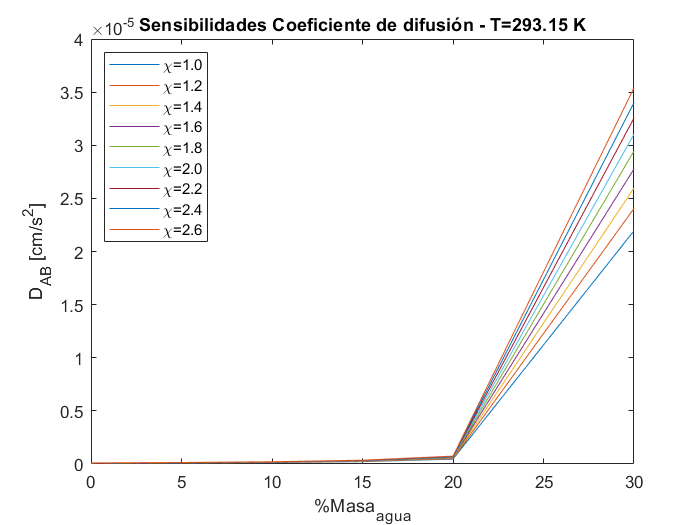

j=1;
for fact_aso=1:0.2:2.6
    Diff_sens(:,j)=(7.4e-8)*((fact_aso.^0.5*PM_Mezcla.^0.5.*Temperature)./(Viscosidad_Eth.*Vol_molar.^0.6));
    plot(water_content_Eth,Diff_sens(:,j)), hold on
    j=j+1; 
end
title('Sensibilidades Coeficiente de difusión - T=293.15 K')
xlabel('%Masa_a_g_u_a'), ylabel('D_A_B [cm/s^2]')
legend('\chi=1.0','\chi=1.2','\chi=1.4','\chi=1.6','\chi=1.8','\chi=2.0','\chi=2.2','\chi=2.4','\chi=2.6','Location','northwest')
hold off

Flux=Diff_sens.*concentr_Eth

Flux =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


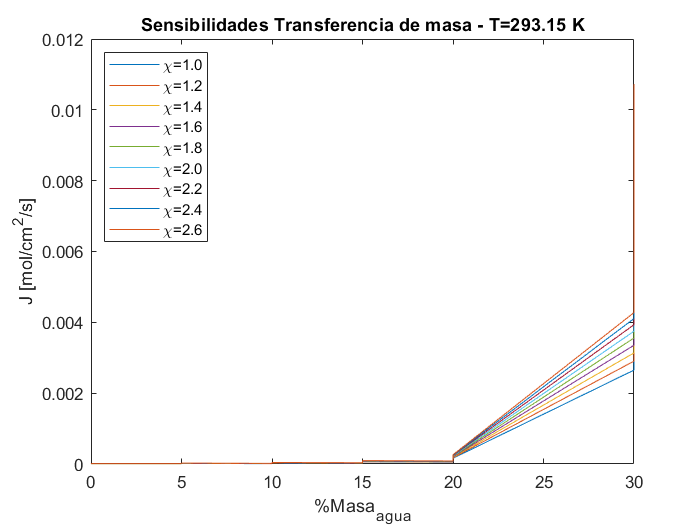


for k=1:9
    plot(water_content_Eth,Flux(:,k)), hold on 
end
title('Sensibilidades Transferencia de masa - T=293.15 K')
xlabel('%Masa_a_g_u_a'), ylabel('J [mol/cm^2/s]')
legend('\chi=1.0','\chi=1.2','\chi=1.4','\chi=1.6','\chi=1.8','\chi=2.0','\chi=2.2','\chi=2.4','\chi=2.6','Location','northwest')
hold off